%% Pick and Place Starter Code
%
% This script shows how to use the motion control utilities to command the
% robot to pickup a bottle and drop it off at bin by using a sequential
% approach

% Execute each section individually and visualize result in Gazebo

%% Setup
rosIP = "172.18.0.1" % Change IP address!!    % IP address of ROS enabled machine  

rosIP = "172.18.0.1"

rosshutdown; % shut down existing connection to ROS

Shutting down global node /matlab_global_node_92389 with NodeURI http://PCIrandi:37967/ and MasterURI http://172.18.0.1:11311.


rosinit(rosIP,11311);

Initializing global node /matlab_global_node_39367 with NodeURI http://PCIrandi:35741/ and MasterURI http://172.18.0.1:11311.


% rosinit(rosIP,'NodeHost','192.168.206.1')

[gripAct,gripGoal] = rosactionclient('/gripper_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory','DataFormat','struct')

gripAct =   SimpleActionClient with properties:

           ActionName: '/gripper_controller/follow_joint_trajectory'
           ActionType: 'control_msgs/FollowJointTrajectory'
    IsServerConnected: 0
                 Goal: [1×1 struct]
            GoalState: ''
        ActivationFcn: @(~)disp('Goal active')
          FeedbackFcn: @(~,msg)disp(['Feedback: ',showDetailsAnyFormat(msg)])
            ResultFcn: @(~,res)disp(['Final state ',res.State,' with result: ',showDetailsAnyFormat(res.Message)])
           DataFormat: 'struct'


gripGoal = struct with fields:
          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 struct]
        PathTolerance: [0×1 struct]
        GoalTolerance: [0×1 struct]
    GoalTimeTolerance: [1×1 struct]


gripAct.FeedbackFcn = [];
gripAct.ResultFcn = [];

gripPos = 0.115; %0 is fully closed, 4 is fully open
gripGoal=packGripGoal(gripPos,gripGoal)

gripGoal = struct with fields:
          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 struct]
        PathTolerance: [0×1 struct]
        GoalTolerance: [1×1 struct]
    GoalTimeTolerance: [1×1 struct]


sendGoal(gripAct,gripGoal);

[trajAct,trajGoal] = rosactionclient('/pos_joint_traj_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory','DataFormat','struct') 

trajAct =   SimpleActionClient with properties:

           ActionName: '/pos_joint_traj_controller/follow_joint_trajectory'
           ActionType: 'control_msgs/FollowJointTrajectory'
    IsServerConnected: 0
                 Goal: [1×1 struct]
            GoalState: ''
        ActivationFcn: @(~)disp('Goal active')
          FeedbackFcn: @(~,msg)disp(['Feedback: ',showDetailsAnyFormat(msg)])
            ResultFcn: @(~,res)disp(['Final state ',res.State,' with result: ',showDetailsAnyFormat(res.Message)])
           DataFormat: 'struct'


trajGoal = struct with fields:
          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 struct]
        PathTolerance: [0×1 struct]
        GoalTolerance: [0×1 struct]
    GoalTimeTolerance: [1×1 struct]


trajAct.FeedbackFcn = []; 
trajAct.ResultFcn = []; 
jointSub = rossubscriber("/joint_states",'DataFormat','struct')

jointSub =   Subscriber with properties:

                      TopicName: '/joint_states'
                  LatestMessage: []
                    MessageType: 'sensor_msgs/JointState'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: []
                     DataFormat: 'struct'


jointStateMsg = jointSub.LatestMessage


jointStateMsg =

     []




UR5e = loadrobot('universalUR5e')

UR5e =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


initialIKGuess = homeConfiguration(UR5e);

% Adjust body transformations from previous URDF version
tform=UR5e.Bodies{3}.Joint.JointToParentTransform;
UR5e.Bodies{3}.Joint.setFixedTransform(tform*eul2tform([pi/2,0,0]));
tform=UR5e.Bodies{4}.Joint.JointToParentTransform;
UR5e.Bodies{4}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));
tform=UR5e.Bodies{7}.Joint.JointToParentTransform;
UR5e.Bodies{7}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));

ik = inverseKinematics("RigidBodyTree",UR5e); % Create Inverse kinematics solver
ikWeights = [0.25 0.25 0.25 0.1 0.1 .1]; % configuration weights for IK solver [Translation Orientation] see documentation

%% Set Init Configuration
% A good initial condition will help the inverse kinematics algorithm
% maintain the elbow away from the table
initialIKGuess(3).JointPosition = 0.3; initialIKGuess(1).JointPosition = -1.5;
trajGoal = packTrajGoal(initialIKGuess,trajGoal)

trajGoal = struct with fields:
          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 struct]
        PathTolerance: [0×1 struct]
        GoalTolerance: [1×6 struct]
    GoalTimeTolerance: [1×1 struct]


sendGoal(trajAct,trajGoal); 

%% Send new configuration (Align with bottle)
jointStateMsg = receive(jointSub,5) % receive current robot configuration

jointStateMsg = struct with fields:
    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 struct]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]


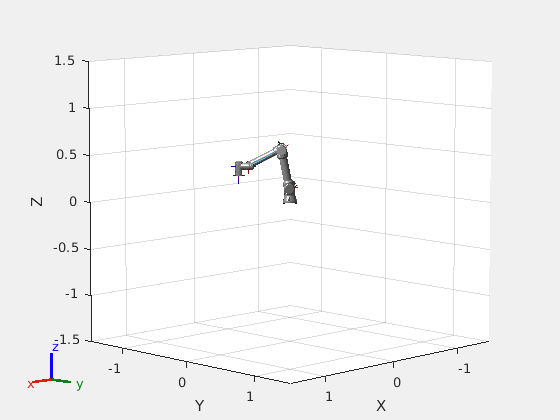

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(UR5e,packIKGuess(initialIKGuess,jointStateMsg))


gripperTranslation = [0.46 -0.07 0.3]; gripperRotation = [pi/2 -pi 0]; %  [Z Y X]radians

tform = eul2tform(gripperRotation); tform(1:3,4) = gripperTranslation'; % set translation in homogeneous transform
[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
trajGoal = packTrajGoal(configSoln,trajGoal);
sendGoal(trajAct,trajGoal); 

%% Approach bottle and close gripper
jointStateMsg = receive(jointSub,5) % receive current robot configuration

jointStateMsg = struct with fields:
    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 struct]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]



gripperTranslation = [0.46 -0.07 0.24]; gripperRotation = [pi/2 -pi 0]; %  [Z Y X]radian

tform = eul2tform(gripperRotation); tform(1:3,4) = gripperTranslation'; % set translation in homogeneous transform
[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
trajGoal = packTrajGoal(configSoln,trajGoal); sendGoal(trajAct,trajGoal); 
%% Close gripper
gripGoal=packGripGoal(0.517,gripGoal)

gripGoal = struct with fields:
          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 struct]
        PathTolerance: [0×1 struct]
        GoalTolerance: [1×1 struct]
    GoalTimeTolerance: [1×1 struct]


sendGoal(gripAct,gripGoal);

%% Lift bottle 
jointStateMsg = receive(jointSub,5) % receive current robot configuration

jointStateMsg = struct with fields:
    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 struct]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]



gripperTranslation = [0.46 -0.07 0.3]; gripperRotation = [pi/2 -pi 0]; %  [Z Y X]radian

tform = eul2tform(gripperRotation); tform(1:3,4) = gripperTranslation'; % set translation in homogeneous transform
[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
trajGoal = packTrajGoal(configSoln,trajGoal); sendGoal(trajAct,trajGoal); 

%% Place bottle above bin
jointStateMsg = receive(jointSub,5) % receive current robot configuration

jointStateMsg = struct with fields:
    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 struct]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]



gripperTranslation = [0.46 -0.3 0.3]; gripperRotation = [pi/2 -pi 0]; %  [Z Y X]radian

tform = eul2tform(gripperRotation); tform(1:3,4) = gripperTranslation'; % set translation in homogeneous transform
[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
trajGoal = packTrajGoal(configSoln,trajGoal); sendGoal(trajAct,trajGoal); 

%% Open gripper
gripGoal=packGripGoal(0.1,gripGoal)

gripGoal = struct with fields:
          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 struct]
        PathTolerance: [0×1 struct]
        GoalTolerance: [1×1 struct]
    GoalTimeTolerance: [1×1 struct]


sendGoal(gripAct,gripGoal);

%% Helper functions
function initialIKGuess = packIKGuess(initialIKGuess,jointStateMsg)
    initialIKGuess(1).JointPosition = jointStateMsg.Position(4); % update configuration in initial guess
    initialIKGuess(2).JointPosition = jointStateMsg.Position(3);
    initialIKGuess(3).JointPosition = jointStateMsg.Position(1);
    initialIKGuess(4).JointPosition = jointStateMsg.Position(5);
    initialIKGuess(5).JointPosition = jointStateMsg.Position(6);
    initialIKGuess(6).JointPosition = jointStateMsg.Position(7);
end